clear all;
clc;


% Regression CNN model for PM2.5

% Data preparation
myFolder = 'C:\Users\cjoyc\Desktop\Capstone\figuredata';
% PM2.5 measurements 
PMtbl = readtable('PMdata.csv');
fileName_array = PMtbl.('fileName');
PM25_array = PMtbl.("PM25");

% M x N is the image size
M = 250;%960;
N = 250;%1280;

% First, load the images into 4D arrays
imageArray = zeros(M,N,3,206); % Where N and M are your image size

% Get a list of all files in the folder with the desired file name pattern.
filePattern = fullfile(myFolder, '*.jpg'); % Change to whatever pattern you need.
theFiles = dir(filePattern);
numFiles = length(theFiles);
Xdata = zeros(M,N,3,numFiles);
Ydata = zeros(numFiles,1);
scale = 0.5;

for k = 1 : numFiles
  baseFileName = theFiles(k).name;
  fullFileName = fullfile(myFolder, baseFileName);
  %fprintf(1, 'Now reading %s\n', fullFileName);
  % Now do whatever you want with this file name,
  % Pair the file name with the corresponding PM2.5 in the .txt
  I = imread(fullFileName);
  J = imresize(I,[M,N]);
  Xdata(:,:,:,k) = J;
  for k1 = 1:numFiles
    if strcmpi(baseFileName,fileName_array(k1))
        Ydata(k) = PM25_array(k1);
    end
  end
  %patients(patients.Gender == "Male"
 % Ydata = PMtbl.fileName == baseFileName,1);
end

size_of_imageArray= size(imageArray);

% Split data into training and test arrays

%[Xtrain,X,Val,Xtest] = dividerand(Xdata,0.8,0,0.2);
% randomly select indexes to split data into 70%
% training set, 0% validation set and 30% test set.
[train_idx, val_idx, test_idx] = dividerand(206, 0.7, 0.1, 0.2);
% slice training data with train indexes
%(take training indexes in all 10 features)
XTrain = Xdata(:,:,:,train_idx);
YTrain = Ydata(train_idx);
% select test data
XTest = Xdata(:,:,:,test_idx);
YTest = Ydata(test_idx);

XValidation = Xdata(:,:,:, val_idx);
YValidation = Ydata(val_idx);

layers = [
    imageInputLayer([M N 3])
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)
    dropoutLayer(0.25)

    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)
    dropoutLayer(0.25)

    convolution2dLayer(3,128,'Padding','same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2,'Stride',2)
    dropoutLayer(0.4)

    flattenLayer
    fullyConnectedLayer(128)
    reluLayer
    dropoutLayer(0.3)
    fullyConnectedLayer(1)
    regressionLayer];

miniBatchSize  = 30;
validationFrequency = floor(numel(YTrain)/miniBatchSize);
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',30, ...
    'InitialLearnRate',1e-4, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropFactor',0.1, ...
    'LearnRateDropPeriod',20, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{XValidation,YValidation}, ...
    'ValidationFrequency',validationFrequency, ...
    'Plots','training-progress', ...
    'Verbose',false);

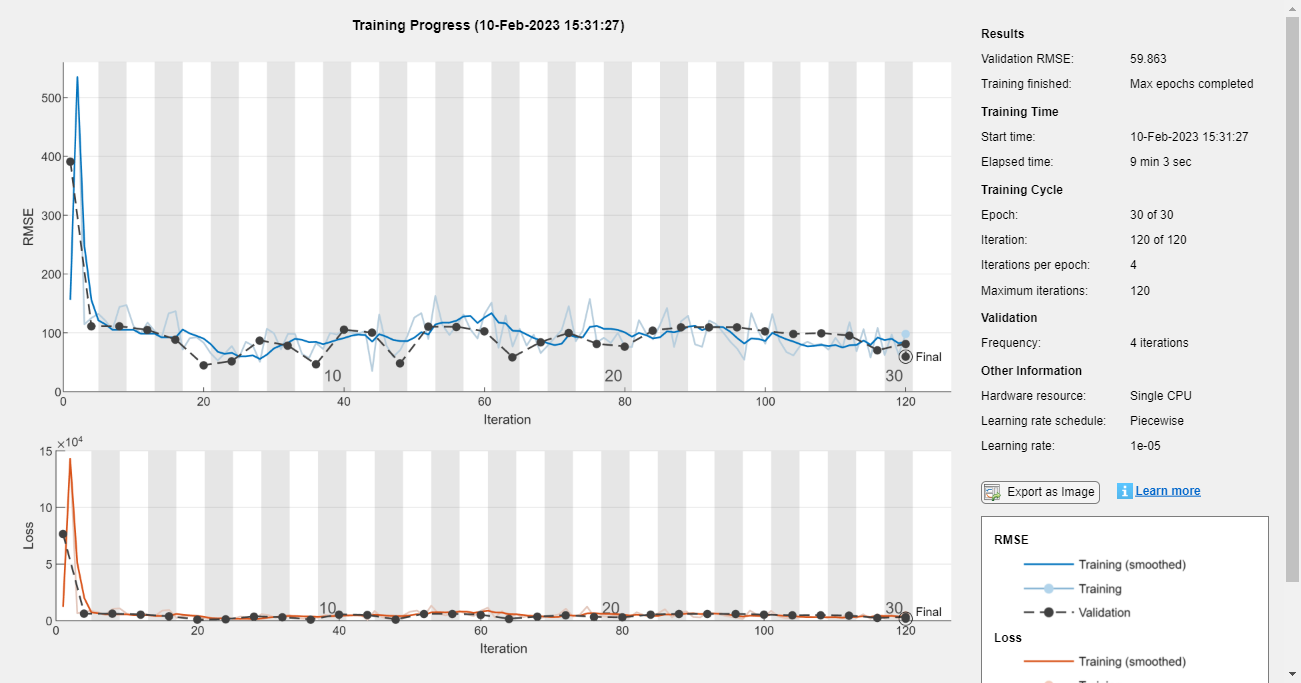

net = trainNetwork(XTrain,YTrain,layers,options);

net.Layers

ans =   22×1 Layer array with layers:

     1   'imageinput'         Image Input           250×250×3 images with 'zerocenter' normalization
     2   'conv_1'             2-D Convolution       32 3×3×3 convolutions with stride [1  1] and padding 'same'
     3   'batchnorm_1'        Batch Normalization   Batch normalization with 32 channels
     4   'relu_1'             ReLU                  ReLU
     5   'maxpool_1'          2-D Max Pooling       2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'dropout_1'          Dropout               25% dropout
     7   'conv_2'             2-D Convolution       32 3×3×32 convolutions with stride [1  1] and padding 'same'
     8   'batchnorm_2'        Batch Normalization   Batch normalization with 32 channels
     9   'relu_2'             ReLU                  ReLU
    10   'maxpool_2'          2-D Max Pooling       2×2 max pooling with stride [2  2] and

YPredicted = predict(net,XTest);

predictionError = YTest - YPredicted;
YTest

YTest =    342
   336
   341
   420
   436
    12
    13
    14
    87
    85


YPredicted

YPredicted = 41×1 single column vector
   96.2485
   28.9810
  174.5418
  133.5172
  156.3855
    3.3304
    3.1692
    3.1318
  142.5882
   47.8832
